# 声学工具箱使用

## kraken使用：

clc;clear;
kraken testEnvs\MunkK;

绘制传播损失

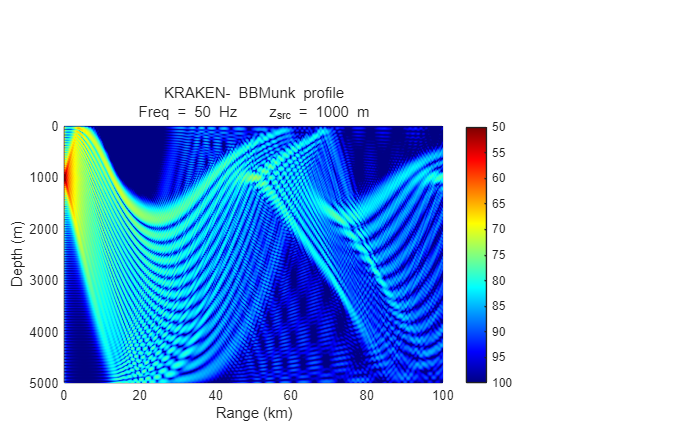

%传播损失
global units;
units = 'km';%这样输出单位为km
figure;
plotshd testEnvs\MunkK.shd.mat;%此处注意添加.mat

绘制随深度变化的传播损失

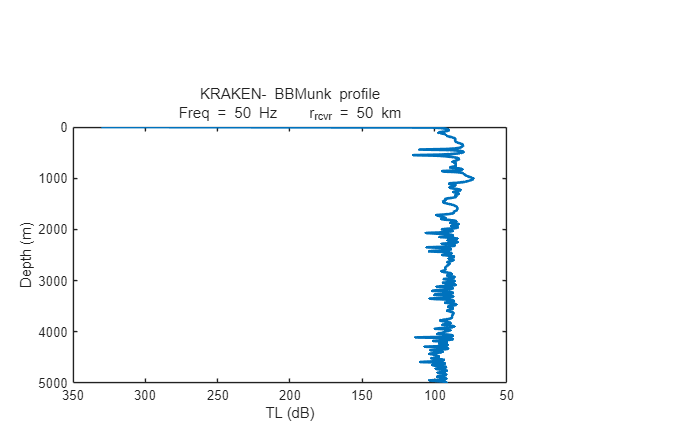

PlotTLd uses the first bearing and source depth in the shade file; check OK


figure;
plottld('testEnvs\MunkK.shd.mat',50);%50km处随深度变化的传播损失

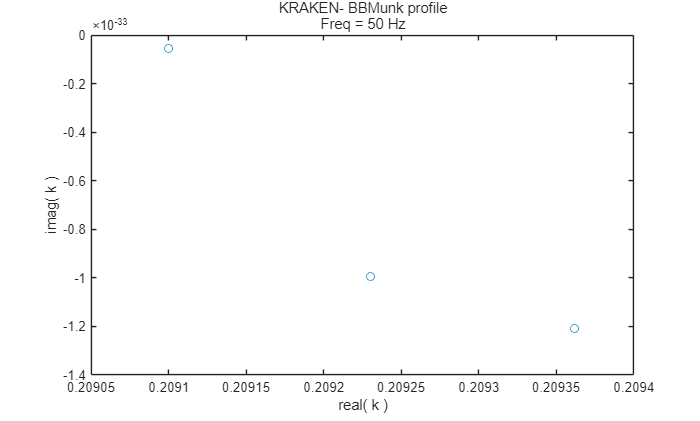

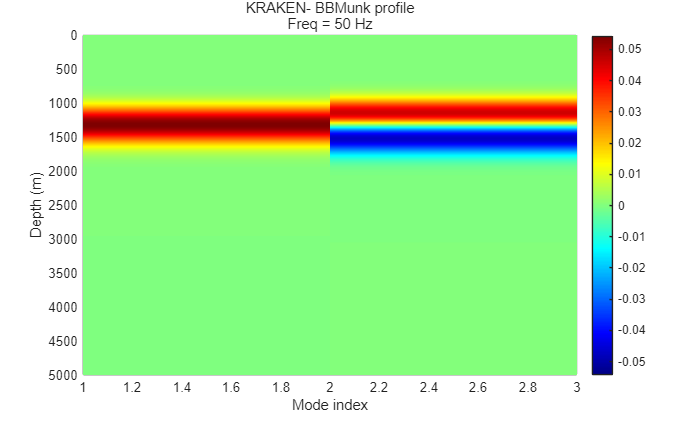

figure
plotmode('testEnvs\MunkK.mod',0,[1  2  3]);

如何读取声场

bellhop  'testEnvs\pekeris';

STOP Fatal Error: Check the print file for details


figure 
plotray('testEnvs\pekeris');

testEnvs\pekeris.ray


错误使用 plotray (第 23 行)
No ray file exists; you must run BELLHOP first (with ray ouput selected)


% [ PlotTitle, PlotType, freqVec, freq0, atten, Pos, pressure ] = read_shd( 'testEnvs\MunkK.shd.mat' );
% %load(MunkK.shd.mat);


用代码编写环境文件

[ TitleEnv, freq, SSP, Bdry, Pos, Beam, cInt, RMax, fid ] = read_env('testEnvs\MunkK.env','KRAKEN');

__________________________________________________________________
BBMunk profile
Frequency = 50 Hz 
Number of media = 1 

    N2-Linear approximation to SSP
    Attenuation units: dB/wavelength
    VACUUM

     z (m)     alphaR (m/s)      betaR       rho (g/cm^3)    alphaI        betaI 
    ( Number of pts = 0  Roughness =   0.00  Depth =  5000.00 ) 
      0.00       1548.52          0.00          1.00        0.0000        0.0000 
    200.00       1530.29          0.00          1.00        0.0000        0.0000 
    250.00       1526.69          0.00          1.00        0.0000        0.0000 
    400.00       1517.78          0.00          1.00        0.0000        0.0000 
    600.00       1509.49          0.00          1.00        0.0000        0.0000 
    800.00       1504.30          0.00          1.00        0.0000        0.0000 
   1000.00       1501.38          0.00          1.00        0.0000        0.0000 
   1200.00       1500.14          0.00          1.00        0.0000      

fclose all;
write_env( 'testEnvs\MunkK_writtenByMe', 'KRAKEN', TitleEnv, freq, SSP, Bdry, Pos, Beam, cInt, RMax);

读取声场的函数

## Bellhop的使用：

绘制传播损失

bellhop testEnvs\MunkB_Coh;
clc
figure
plotshd('testEnvs\MunkB_Coh.shd');

__________________________________________________________________
Munk profile, coherent
Frequency = 5000 Hz 
Number of media = 1 

    Spline approximation to SSP
    Attenuation units: dB/wavelength
    VACUUM

     z (m)     alphaR (m/s)      betaR       rho (g/cm^3)    alphaI        betaI 
    ( Number of pts = 51  Roughness =   0.00  Depth =  5000.00 ) 
      0.00       1548.52          0.00          1.00        0.0000        0.0000 
    200.00       1530.29          0.00          1.00        0.0000        0.0000 
    250.00       1526.69          0.00          1.00        0.0000        0.0000 
    400.00       1517.78          0.00          1.00        0.0000        0.0000 
    600.00       1509.49          0.00          1.00        0.0000        0.0000 
    800.00       1504.30          0.00          1.00        0.0000        0.0000 
   1000.00       1501.38          0.00          1.00        0.0000        0.0000 
   1200.00       1500.14          0.00          1.00        0.00

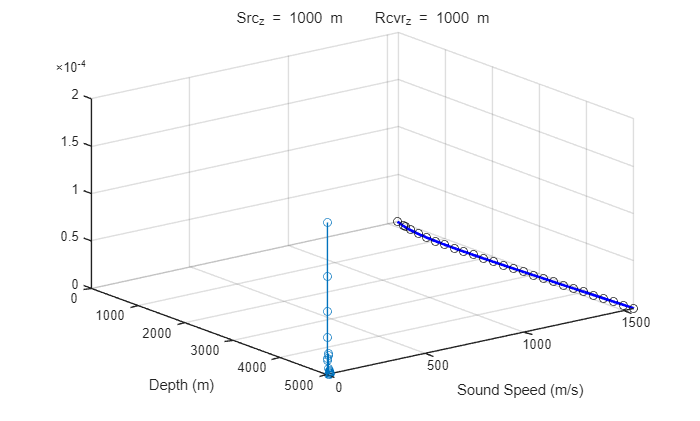

plotssp('testEnvs\MunkB_Coh');

bellhop arr

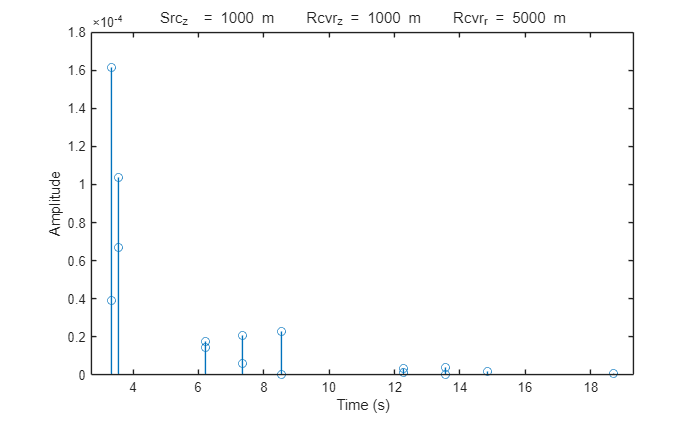

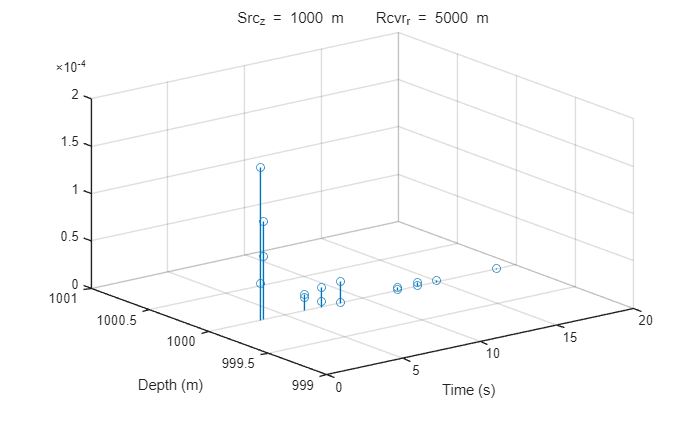

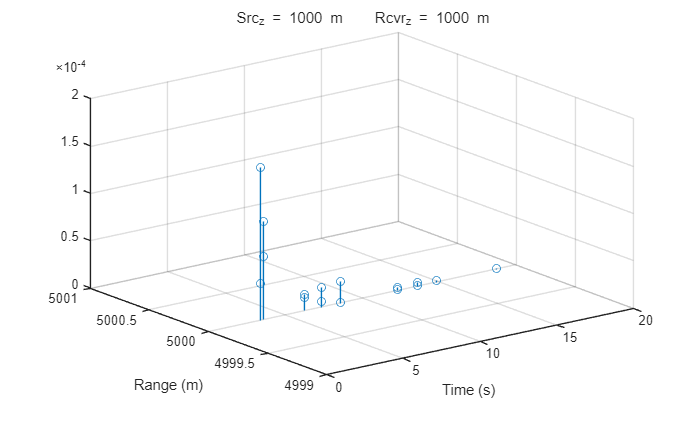

bellhop ('testEnvs\MunkB_Arr');
figure
plotarr('testEnvs\MunkB_Arr.arr',1,1,1);grid on;

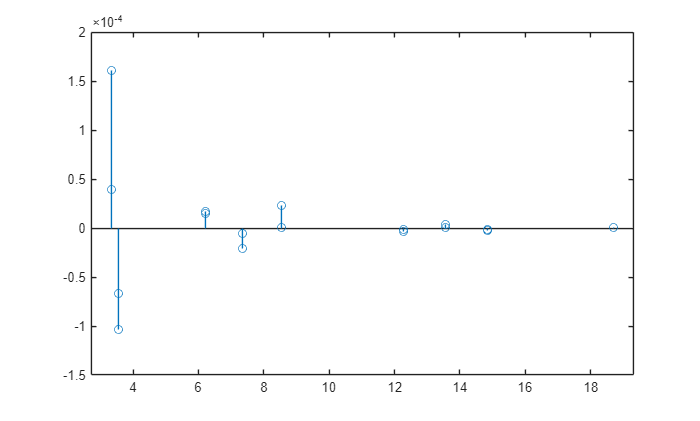


[ Arr, Pos ] = read_arrivals_asc( 'testEnvs\MunkB_Arr.arr' );
Amp = real(Arr.A);%到达幅度
delay = Arr.delay;%到达时延


Amp_Delay = [delay;Amp];
Amp_Delay(:,all(Amp_Delay==0,1))=[]; %去掉0值
Amp_Delay=sortrows(Amp_Delay',1);  %按照时延从小到大排序
figure
stem(Amp_Delay(:,1),Amp_Delay(:,2));

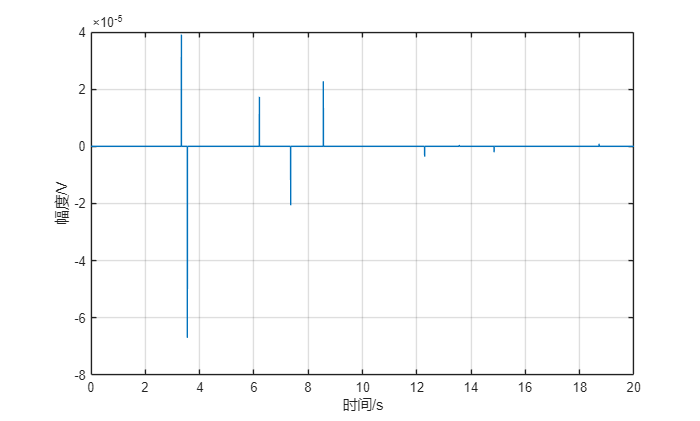

% 定义时间参数
fs = 20e3;
t = 0:1/fs:20 - 1/fs; % 时间向量，这里生成0到0.14秒的时间序列，采样间隔为1/fs
Ts = 1/fs;
IR = zeros(1,length(t));
%将bellhop得到的序列插入进单位脉冲响应中
delayIndex = round(Amp_Delay(:,1)./Ts);
for i = 1:length(delayIndex)
    IR(delayIndex(i)) = Amp_Delay(i,2);
end
figure
plot(t,IR);xlabel('时间/s');ylabel('幅度/V');grid on;

绘制声线


bellhop testEnvs\MunkB_ray
figure
plotray('testEnvs\MunkB_ray.ray');


本征声线

bellhop testEnvs\MunkB_EngRay;
figure
plotray('testEnvs\MunkB_EngRay.ray');